close all; clear; clc
DSM_constants;

%========= Calculs préliminaires ================

% masse totale du système

    m_r = (pi*D_r*D_r*L_r/4 - pi*D_i*D_i*(L_r-L_a)/4 - pi*D_a*D_a*L_a/4)*rho_r + (pi*D_a*D_a*L_a/4- pi*D_i*D_i*L_a/4)*rho_a; % masse totale

% masse des différents composants

    m_a = pi*(D_a*D_a - D_i*D_i)/4*L_a*rho_a; % masse aimant
    m_r1 = pi*(D_r*D_r - D_a*D_a)/4*L_a*rho_r; % masse autour aimant
    m_r2 = pi*(D_r*D_r - D_i*D_i)/4*(L_r - L_a) * rho_r; % reste de la masse

% position du centre de gravité
   
    z_CG = (m_a*L_a/2 + m_r1*L_a/2 + m_r2*(3*L_r/4))/m_r; % depuis le point le plus à gauche
    z_CGcentre = z_CG - L_r/2; % centre de masse sur z par rapport au centre
    y_CGcentre = 0; % centre de masse sur y par rapport au centre

% distance des supports et du balourd du CG

    z_support1CG = -(z_CG - z_sup1); % position du support 1 par rapport au CG
    z_support2CG = z_sup2 - z_CG; % position du support 2 par rapport au CG
    z_balourdCG = z_CGcentre + L_a/2; % position du balourd par rapport au CG

% Moment d'interties
    
    J_rz = pi/32*(rho_r*(L_r - L_a)*(D_r^4 - D_i^4) + rho_a*L_a*(D_a^4 - D_i^4) + rho_r*L_a*(D_r^4 - D_a^4)); % moment d'intertie z du rotor

    % formule pour un cylindre creux autour de leur centre de gravité: 
    % J_y = J_x = (1/12)*M*(3*R_i + 3*R_e + l^2)

    J_y2cg = (1/12)*m_r2*(3*(D_r/2)^2 + 3*(D_i/2)^2 + (L_r - L_a)^2);
    J_y1cg = (1/12)*m_r1*(3*(D_r/2)^2 + 3*(D_a/2)^2 + L_a^2);
    J_y3cg = (1/12)*m_a*(3*(D_a/2)^2 + 3*(D_i/2)^2 + L_a^2);
    
    % calcul des interties au CG du rotor

    J_y1 = J_y1cg + m_r1*(z_CG - L_a/2)^2;
    J_y2 = J_y2cg + m_r2*(L_a/2 + 0.5*L_r - z_CG)^2; 
    J_y3 = J_y3cg + m_a*(z_CG - L_a/2)^2;

    J_ry = J_y1 + J_y2 + J_y3; % Inertie totale du rotor autour de y


% Rigidités de la courroie

    k_c1 = E_c * h_c * t_c / l_c1;
    k_c2 = E_c * h_c * t_c / l_c2;
    k_c3 = E_c * h_c * t_c / l_c3;
    k_c4 = E_c * h_c * t_c / l_c4;
    k_c5 = E_c * h_c * t_c / l_c5;
    k_c6 = E_c * h_c * t_c / l_c6;
    k_c7 = E_c * h_c * t_c / l_c7;


% Inerties et rigidités des lames

    I_lx=t_l*(h_l^3)/12;
    I_lz=h_l*(t_l^3)/12;

    kl_x = 12*E_l*I_lz/L_l^3;
    kl_z = 12*E_l*I_lx/L_l^3;

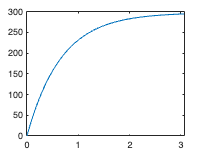

%========= Accélération du groupe d'entraînement ================

% Rapports de transmission

    % Rapport de transmission moteur-courroie

    i_mc = 1 / (D_m / 2);

    % Rapport de transmission courroie-poulie

    i_cp = D_p / 2;

    % Rapport de transmission moteur-poulie

    i_mp = i_mc * i_cp;
    % i_mp = D_p / D_m;

    % Rapport de transmission moteur-rotor

    i_mr = D_r / D_m;
    % i_mr2 = i_mc * D_r

% Vitesse stationnaire du moteur
    
    w_rs2 = w_rs * 2*pi/60;
    w_ms = w_rs2 * i_mr;%rad/s

% Moments d'inertie réduits
    
    % Moment d'inertie réduit moteur
    J_mz_red = J_mz;

    % Moment d'inertie réduit poulie
    J_pz_red = J_pz/(i_mp)^2;

    % Moment d'inertie réduit rotor
    J_rz_red = J_rz/(i_mr)^2;

% Couple résistant rotor

    b_r = T_resNulle;
    a_r = (T_resMax - b_r) / w_rs2;

% Couple résistant rotor réduit

    %Coeff. b couple rotor réduit
    b_r_red = T_resNulle/i_mr;

    %Coeff. a couple rotor réduit
    a_r_red = (T_resMax/i_mr - b_r_red)/w_ms;

%Moment d'inertie réduit du système entraînement (global)

    J_z_red = J_mz_red + 5*J_pz_red + J_rz_red;

%Couple moteur

    Tm = a_r_red*w_ms + b_r_red;

    %Coeff. b couple moteur
    b_m = Tm;

    %Coeff. a couple moteur
    a_m = 0;

    %Coeff. a couple système d'entraînement (globale)
    a_red = -a_r_red + a_m;

    %Coeff. b couple système d'entraînement (globale)(couple système
    %d'entraînement = couple moteur - couple rotot (résistant)
    b_red = -b_r_red + b_m;

% Temps de démaragge système d'entraînement

t_d_99 = J_z_red/a_red*log(0.99*a_red/b_red*w_ms+1);

%Courbe de d'accélération
t=linspace(0,t_d_99,100);

w_m = b_red/a_red*(exp(a_red/J_z_red*t)-1);

%accélération groupe d'entraînement
a_m = b_red/J_z_red*exp(a_red/J_z_red*t);
figure(1)
plot(t,w_m)

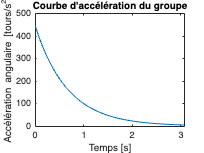

figure(2)
plot(t,a_m)
title("Courbe d'accélération du groupe")
xlabel('Temps [s]') 
ylabel('Accélération angulaire [tours/s^2]') 

%========= Analyse dynamique du groupe d'entraînement ================

% Rigidités courroie réduites
    
    k_c1_red = k_c1 / i_mc^2;
    k_c2_red = k_c2 / i_mc^2;
    k_c3_red = k_c3 / i_mc^2;
    k_c4_red = k_c4 / i_mc^2;
    k_c5_red = k_c5 / i_mc^2;
    k_c6_red = k_c6 / i_mc^2;
    k_c7_red = k_c7 / i_mc^2;

% Vitesse critique minimale

    % équations de mouvement des 7 masses
    % [M](d^2/dt^2)theta + [K]theta = Q*

    M = diag([J_mz_red J_rz_red J_pz_red J_pz_red J_pz_red J_pz_red J_pz_red]);
    %Raideur equivalente pour schéma du modèle dynamique réduit et simplifié
    K = [k_c1_red+k_c7_red, 0, -k_c1_red, 0, 0, 0, -k_c7_red
         0, k_c6_red+k_c5_red, 0,0, 0, -k_c5_red, -k_c6_red
         -k_c1_red, 0, k_c2_red+k_c1_red, -k_c2_red, 0, 0, 0
         0, 0, -k_c2_red, k_c3_red+k_c2_red, -k_c3_red, 0, 0
         0, 0, 0, -k_c3_red, k_c4_red+k_c3_red, -k_c4_red, 0
         0, -k_c5_red, 0, 0, -k_c4_red, k_c5_red+k_c4_red, 0
         -k_c7_red, -k_c6_red, 0, 0, 0, 0, k_c7_red+k_c6_red];
    
    N = (inv(M)*K);

    [V,D] = eig(N);

    diagonal = diag(D);
    sorted_diag = sort(diagonal);
    criticalFreq = sorted_diag(2);

    w_m0_min = sqrt(criticalFreq)/(2*pi)*60/i_mr;


    beta = w_rs/w_m0_min;


% Vitesse critique du modèle réduit simplifié

    K_equivalent1 = 1/(1/k_c1_red+1/k_c2_red+1/k_c3_red+1/k_c4_red+1/k_c5_red);
    K_equivalent2 = (k_c7_red*k_c6_red)/(k_c7_red+k_c6_red);
    K_c_tot_red = K_equivalent1+K_equivalent2;

    w0_simp = sqrt(K_c_tot_red*(1/J_mz_red+1/J_rz_red))/(2*pi)*60;

% Erreur relative sur la vitesse critique minimale

    erreur_w0 = (w0_simp/i_mr-w_m0_min)/w_m0_min;

%========= Réponse forcée du rotor ================

%Plage du balourd

    m_BalourdMin = D_r/2 * m_r *0.00001;
    m_BalourdMax = D_r/2 * m_r * 0.001;
    plageBalourd = [m_BalourdMin, m_BalourdMax];


% Calcul pour trouver m_s
    L_s1 = L_r/2 + z_CGcentre;
    L_s2 = L_r/2 - z_CGcentre;
    % Assumes all required constants are already defined:
    % m_r, J_rz_red, L_s1, L_s2, kl_x, d, plageBalourd, etendue_mesure
    
    d = z_CG - L_a/2; 
    
    
    ms = linspace(0.001, 0.1, 1000);         % ms sweep
    D = [1; d];
    
    for i = 1:length(ms)
        m_s = ms(i);
        isValid = true;  % Assume valid unless proven otherwise
        
        % Mass and stiffness matrices
        M = [(m_r + 2*m_s),            m_s*(L_s2 - L_s1);
             m_s*(L_s2 - L_s1),        J_rz + m_s*(L_s1^2 + L_s2^2)];
        
        K = [4*kl_x,                   2*kl_x*(L_s2 - L_s1);
             2*kl_x*(L_s2 - L_s1),     2*kl_x*(L_s1^2 + L_s2^2)];
        
        % Eigenvalue problem to get natural frequency
        eigenvalues = eig(M \ K);
        natural_frequencies = sqrt(eigenvalues);  % rad/s

        w_max = max(natural_frequencies)
        
        buffer = 0.01;  % 1% buffer
        omega = linspace(w_max * (1 + buffer), 1257, 1000);   % omega sweep
        
        for j = 1:length(omega)
            
            w = omega(j);
            
        
            invertedMatrix = (K - w^2 * M)\eye(2);
        
            % Compute accelerations for both min and max imbalance
            accelVect_min = w^4 * m_BalourdMin * (invertedMatrix * D);
            accelVect_max = w^4 * m_BalourdMax * (invertedMatrix * D);
        
            accel_x_min = accelVect_min(1);
            accel_theta_min = accelVect_min(2);
            accel_x_max = accelVect_max(1);
            accel_theta_max = accelVect_max(2);
        
            accel_x1_min = abs(accel_x_min - L_s1 * accel_theta_min);
            accel_x2_min = abs(accel_x_min + L_s2 * accel_theta_min);
            accel_x1_max = abs(accel_x_max - L_s1 * accel_theta_max);
            accel_x2_max = abs(accel_x_max + L_s2 * accel_theta_max);
        
            % If any acceleration is outside the measurement range, m_s is not valid
            if any([accel_x1_min, accel_x1_max, accel_x2_min, accel_x2_max] < etendue_mesure(1)) || ...
               any([accel_x1_min, accel_x1_max, accel_x2_min, accel_x2_max] > etendue_mesure(2))
               isValid = false;
                break;  % No need to check other ω
            end
         end

      if isValid
          fprintf('Minimal valid m_s for ALL ω: %.4f\n', m_s);
          break;
      end
   end

w_max = 5.0497e+03

w_max = 4.8387e+03

w_max = 4.6521e+03

w_max = 4.4855e+03

w_max = 4.3356e+03

w_max = 4.1998e+03

w_max = 4.0761e+03

w_max = 3.9626e+03

w_max = 3.8582e+03

w_max = 3.7615e+03

w_max = 3.6718e+03

w_max = 3.5882e+03

w_max = 3.5101e+03

w_max = 3.4369e+03

w_max = 3.3681e+03

w_max = 3.3032e+03

w_max = 3.2420e+03

w_max = 3.1840e+03

w_max = 3.1290e+03

w_max = 3.0768e+03

w_max = 3.0272e+03

w_max = 2.9798e+03

w_max = 2.9346e+03

w_max = 2.8914e+03

w_max = 2.8501e+03

w_max = 2.8104e+03

w_max = 2.7724e+03

w_max = 2.7359e+03

w_max = 2.7008e+03

w_max = 2.6670e+03

w_max = 2.6345e+03

w_max = 2.6031e+03

w_max = 2.5728e+03

w_max = 2.5435e+03

w_max = 2.5153e+03

w_max = 2.4879e+03

w_max = 2.4614e+03

w_max = 2.4358e+03

w_max = 2.4109e+03

w_max = 2.3868e+03

w_max = 2.3633e+03

w_max = 2.3406e+03

w_max = 2.3185e+03

w_max = 2.2970e+03

w_max = 2.2761e+03

w_max = 2.2558e+03

w_max = 2.2360e+03

w_max = 2.2167e+03

w_max = 2.1979e+03

w_max = 2.1796e+03

w_max = 2.1617e+03

w_max = 2.1443e+03

w_max = 2.1273e+03

w_max = 2.1106e+03

w_max = 2.0944e+03

w_max = 2.0785e+03

w_max = 2.0630e+03

w_max = 2.0478e+03

w_max = 2.0330e+03

w_max = 2.0184e+03

w_max = 2.0042e+03

w_max = 1.9903e+03

w_max = 1.9767e+03

w_max = 1.9633e+03

w_max = 1.9502e+03

w_max = 1.9374e+03

w_max = 1.9248e+03

w_max = 1.9124e+03

w_max = 1.9003e+03

w_max = 1.8884e+03

w_max = 1.8768e+03

w_max = 1.8653e+03

w_max = 1.8541e+03

w_max = 1.8431e+03

w_max = 1.8322e+03

w_max = 1.8215e+03

w_max = 1.8111e+03

w_max = 1.8008e+03

w_max = 1.7907e+03

w_max = 1.7807e+03

w_max = 1.7709e+03

w_max = 1.7613e+03

w_max = 1.7518e+03

w_max = 1.7425e+03

w_max = 1.7333e+03

w_max = 1.7243e+03

w_max = 1.7154e+03

w_max = 1.7067e+03

w_max = 1.6980e+03

w_max = 1.6895e+03

w_max = 1.6812e+03

w_max = 1.6729e+03

w_max = 1.6648e+03

w_max = 1.6568e+03

w_max = 1.6489e+03

w_max = 1.6411e+03

w_max = 1.6335e+03

w_max = 1.6259e+03

w_max = 1.6184e+03

w_max = 1.6111e+03

w_max = 1.6038e+03

w_max = 1.5966e+03

w_max = 1.5896e+03

w_max = 1.5826e+03

w_max = 1.5757e+03

w_max = 1.5689e+03

w_max = 1.5622e+03

w_max = 1.5556e+03

w_max = 1.5491e+03

w_max = 1.5426e+03

w_max = 1.5362e+03

w_max = 1.5299e+03

w_max = 1.5237e+03

w_max = 1.5176e+03

w_max = 1.5115e+03

w_max = 1.5055e+03

w_max = 1.4996e+03

w_max = 1.4937e+03

w_max = 1.4879e+03

w_max = 1.4822e+03

w_max = 1.4765e+03

w_max = 1.4709e+03

w_max = 1.4654e+03

w_max = 1.4599e+03

w_max = 1.4545e+03

w_max = 1.4492e+03

w_max = 1.4439e+03

w_max = 1.4387e+03

w_max = 1.4335e+03

w_max = 1.4284e+03

w_max = 1.4233e+03

w_max = 1.4183e+03

w_max = 1.4133e+03

w_max = 1.4084e+03

w_max = 1.4036e+03

w_max = 1.3988e+03

w_max = 1.3940e+03

w_max = 1.3893e+03

w_max = 1.3846e+03

w_max = 1.3800e+03

w_max = 1.3754e+03

w_max = 1.3709e+03

w_max = 1.3664e+03

w_max = 1.3620e+03

w_max = 1.3576e+03

w_max = 1.3532e+03

w_max = 1.3489e+03

w_max = 1.3447e+03

w_max = 1.3404e+03

w_max = 1.3362e+03

w_max = 1.3321e+03

w_max = 1.3280e+03

w_max = 1.3239e+03

w_max = 1.3199e+03

w_max = 1.3159e+03

w_max = 1.3119e+03

w_max = 1.3080e+03

w_max = 1.3041e+03

w_max = 1.3002e+03

w_max = 1.2964e+03

w_max = 1.2926e+03

w_max = 1.2888e+03

w_max = 1.2851e+03

w_max = 1.2814e+03

w_max = 1.2778e+03

w_max = 1.2741e+03

w_max = 1.2705e+03

w_max = 1.2670e+03

w_max = 1.2634e+03

w_max = 1.2599e+03

w_max = 1.2564e+03

w_max = 1.2530e+03

w_max = 1.2496e+03

w_max = 1.2462e+03

w_max = 1.2428e+03

w_max = 1.2395e+03

w_max = 1.2361e+03

w_max = 1.2329e+03

w_max = 1.2296e+03

w_max = 1.2264e+03

w_max = 1.2231e+03

w_max = 1.2200e+03

w_max = 1.2168e+03

w_max = 1.2137e+03

w_max = 1.2105e+03

w_max = 1.2075e+03

w_max = 1.2044e+03

w_max = 1.2013e+03

w_max = 1.1983e+03

w_max = 1.1953e+03

w_max = 1.1924e+03

w_max = 1.1894e+03

w_max = 1.1865e+03

w_max = 1.1836e+03

w_max = 1.1807e+03

w_max = 1.1778e+03

w_max = 1.1750e+03

w_max = 1.1721e+03

w_max = 1.1693e+03

w_max = 1.1666e+03

w_max = 1.1638e+03

w_max = 1.1610e+03

w_max = 1.1583e+03

w_max = 1.1556e+03

w_max = 1.1529e+03

w_max = 1.1503e+03

w_max = 1.1476e+03

w_max = 1.1450e+03

w_max = 1.1424e+03

w_max = 1.1398e+03

w_max = 1.1372e+03

w_max = 1.1346e+03

w_max = 1.1321e+03

w_max = 1.1296e+03

w_max = 1.1270e+03

w_max = 1.1245e+03

w_max = 1.1221e+03

w_max = 1.1196e+03

w_max = 1.1172e+03

w_max = 1.1147e+03

w_max = 1.1123e+03

w_max = 1.1099e+03

w_max = 1.1075e+03

w_max = 1.1052e+03

w_max = 1.1028e+03

w_max = 1.1005e+03

w_max = 1.0982e+03

w_max = 1.0959e+03

w_max = 1.0936e+03

w_max = 1.0913e+03

w_max = 1.0890e+03

w_max = 1.0868e+03

w_max = 1.0845e+03

w_max = 1.0823e+03

w_max = 1.0801e+03

w_max = 1.0779e+03

w_max = 1.0757e+03

w_max = 1.0736e+03

w_max = 1.0714e+03

w_max = 1.0693e+03

w_max = 1.0671e+03

w_max = 1.0650e+03

w_max = 1.0629e+03

w_max = 1.0608e+03

w_max = 1.0587e+03

w_max = 1.0567e+03

w_max = 1.0546e+03

w_max = 1.0526e+03

w_max = 1.0505e+03

w_max = 1.0485e+03

w_max = 1.0465e+03

w_max = 1.0445e+03

w_max = 1.0425e+03

w_max = 1.0405e+03

w_max = 1.0386e+03

w_max = 1.0366e+03

w_max = 1.0347e+03

w_max = 1.0328e+03

w_max = 1.0308e+03

w_max = 1.0289e+03

w_max = 1.0270e+03

w_max = 1.0251e+03

w_max = 1.0233e+03

w_max = 1.0214e+03

w_max = 1.0195e+03

w_max = 1.0177e+03

w_max = 1.0159e+03

w_max = 1.0140e+03

w_max = 1.0122e+03

w_max = 1.0104e+03

w_max = 1.0086e+03

w_max = 1.0068e+03

w_max = 1.0050e+03

w_max = 1.0033e+03

w_max = 1.0015e+03

w_max = 999.7528

w_max = 998.0109

w_max = 996.2781

w_max = 994.5542

w_max = 992.8393

w_max = 991.1332

w_max = 989.4359

w_max = 987.7472

w_max = 986.0672

w_max = 984.3957

w_max = 982.7327

w_max = 981.0781

w_max = 979.4318

w_max = 977.7938

w_max = 976.1640

w_max = 974.5423

w_max = 972.9286

w_max = 971.3230

w_max = 969.7252

w_max = 968.1353

w_max = 966.5533

w_max = 964.9789

w_max = 963.4122

w_max = 961.8532

w_max = 960.3016

w_max = 958.7576

w_max = 957.2209

w_max = 955.6917

w_max = 954.1697

w_max = 952.6550

w_max = 951.1475

w_max = 949.6471

w_max = 948.1538

w_max = 946.6675

w_max = 945.1882

w_max = 943.7158

w_max = 942.2503

w_max = 940.7916

w_max = 939.3396

w_max = 937.8943

w_max = 936.4557

w_max = 935.0236

w_max = 933.5982

w_max = 932.1792

w_max = 930.7667

w_max = 929.3605

w_max = 927.9608

w_max = 926.5673

w_max = 925.1801

w_max = 923.7991

w_max = 922.4243

w_max = 921.0556

w_max = 919.6929

w_max = 918.3363

w_max = 916.9857

w_max = 915.6410

w_max = 914.3022

w_max = 912.9693

w_max = 911.6422

w_max = 910.3209

w_max = 909.0052

w_max = 907.6953

w_max = 906.3910

w_max = 905.0924

w_max = 903.7993

w_max = 902.5117

w_max = 901.2296

w_max = 899.9530

w_max = 898.6817

w_max = 897.4159

w_max = 896.1553

w_max = 894.9001

w_max = 893.6501

w_max = 892.4054

w_max = 891.1658

w_max = 889.9314

w_max = 888.7021

w_max = 887.4779

w_max = 886.2587

w_max = 885.0446

w_max = 883.8354

w_max = 882.6312

w_max = 881.4318

w_max = 880.2374

w_max = 879.0478

w_max = 877.8630

w_max = 876.6829

w_max = 875.5077

w_max = 874.3371

w_max = 873.1712

w_max = 872.0100

w_max = 870.8534

w_max = 869.7014

w_max = 868.5539

w_max = 867.4110

w_max = 866.2726

w_max = 865.1386

w_max = 864.0091

w_max = 862.8840

w_max = 861.7633

w_max = 860.6469

w_max = 859.5349

w_max = 858.4271

w_max = 857.3237

w_max = 856.2244

w_max = 855.1294

w_max = 854.0386

w_max = 852.9520

w_max = 851.8694

w_max = 850.7910

w_max = 849.7167

w_max = 848.6465

w_max = 847.5803

w_max = 846.5180

w_max = 845.4598

w_max = 844.4055

w_max = 843.3552

w_max = 842.3088

w_max = 841.2662

w_max = 840.2275

w_max = 839.1927

w_max = 838.1617

w_max = 837.1344

w_max = 836.1110

w_max = 835.0912

w_max = 834.0752

w_max = 833.0629

w_max = 832.0543

w_max = 831.0493

w_max = 830.0480

w_max = 829.0503

w_max = 828.0561

w_max = 827.0656

w_max = 826.0785

w_max = 825.0950

w_max = 824.1150

w_max = 823.1385

w_max = 822.1655

w_max = 821.1959

w_max = 820.2297

w_max = 819.2669

w_max = 818.3075

w_max = 817.3515

w_max = 816.3988

w_max = 815.4494

w_max = 814.5033

w_max = 813.5605

w_max = 812.6210

w_max = 811.6848

w_max = 810.7517

w_max = 809.8219

w_max = 808.8953

w_max = 807.9718

w_max = 807.0515

w_max = 806.1343

w_max = 805.2203

w_max = 804.3093

w_max = 803.4015

w_max = 802.4967

w_max = 801.5949

w_max = 800.6962

w_max = 799.8005

w_max = 798.9078

w_max = 798.0181

w_max = 797.1314

w_max = 796.2476

w_max = 795.3667

w_max = 794.4887

w_max = 793.6137

w_max = 792.7415

w_max = 791.8722

w_max = 791.0058

w_max = 790.1422

w_max = 789.2814

w_max = 788.4234

w_max = 787.5683

w_max = 786.7159

w_max = 785.8662

w_max = 785.0193

w_max = 784.1752

w_max = 783.3337

w_max = 782.4950

w_max = 781.6589

w_max = 780.8255

w_max = 779.9948

w_max = 779.1667

w_max = 778.3413

w_max = 777.5185

w_max = 776.6982

w_max = 775.8806

w_max = 775.0656

w_max = 774.2531

w_max = 773.4431

w_max = 772.6357

w_max = 771.8308

w_max = 771.0285

w_max = 770.2286

w_max = 769.4312

w_max = 768.6363

w_max = 767.8438

w_max = 767.0538

w_max = 766.2662

w_max = 765.4811

w_max = 764.6983

w_max = 763.9180

w_max = 763.1400

w_max = 762.3644

w_max = 761.5912

w_max = 760.8203

w_max = 760.0517

w_max = 759.2855

w_max = 758.5216

w_max = 757.7599

w_max = 757.0006

w_max = 756.2436

w_max = 755.4888

w_max = 754.7363

w_max = 753.9860

w_max = 753.2379

w_max = 752.4921

w_max = 751.7485

w_max = 751.0071

w_max = 750.2679

w_max = 749.5308

w_max = 748.7959

w_max = 748.0632

w_max = 747.3326

w_max = 746.6042

w_max = 745.8779

w_max = 745.1537

w_max = 744.4316

w_max = 743.7116

w_max = 742.9937

w_max = 742.2778

w_max = 741.5641

w_max = 740.8524

w_max = 740.1427

w_max = 739.4350

w_max = 738.7294

w_max = 738.0258

w_max = 737.3243

w_max = 736.6247

w_max = 735.9271

w_max = 735.2314

w_max = 734.5378

w_max = 733.8461

w_max = 733.1563

w_max = 732.4685

w_max = 731.7827

w_max = 731.0987

w_max = 730.4167

w_max = 729.7366

w_max = 729.0583

w_max = 728.3820

w_max = 727.7075

w_max = 727.0349

w_max = 726.3642

w_max = 725.6953

w_max = 725.0283

w_max = 724.3631

w_max = 723.6997

w_max = 723.0381

w_max = 722.3784

w_max = 721.7204

w_max = 721.0643

w_max = 720.4099

w_max = 719.7573

w_max = 719.1065

w_max = 718.4575

w_max = 717.8102

w_max = 717.1646

w_max = 716.5208

w_max = 715.8787

w_max = 715.2384

w_max = 714.5998

w_max = 713.9628

w_max = 713.3276

w_max = 712.6940

w_max = 712.0622

w_max = 711.4320

w_max = 710.8035

w_max = 710.1767

w_max = 709.5515

w_max = 708.9279

w_max = 708.3060

w_max = 707.6858

w_max = 707.0671

w_max = 706.4501

w_max = 705.8347

w_max = 705.2209

w_max = 704.6087

w_max = 703.9981

w_max = 703.3890

w_max = 702.7816

w_max = 702.1757

w_max = 701.5714

w_max = 700.9686

w_max = 700.3674

w_max = 699.7678

w_max = 699.1696

w_max = 698.5731

w_max = 697.9780

w_max = 697.3844

w_max = 696.7924

w_max = 696.2019

w_max = 695.6128

w_max = 695.0253

w_max = 694.4392

w_max = 693.8547

w_max = 693.2716

w_max = 692.6899

w_max = 692.1097

w_max = 691.5310

w_max = 690.9538

w_max = 690.3779

w_max = 689.8035

w_max = 689.2306

w_max = 688.6591

w_max = 688.0889

w_max = 687.5202

w_max = 686.9530

w_max = 686.3871

w_max = 685.8226

w_max = 685.2595

w_max = 684.6978

w_max = 684.1374

w_max = 683.5785

w_max = 683.0209

w_max = 682.4646

w_max = 681.9097

w_max = 681.3562

w_max = 680.8040

w_max = 680.2532

w_max = 679.7037

w_max = 679.1555

w_max = 678.6087

w_max = 678.0631

w_max = 677.5189

w_max = 676.9760

w_max = 676.4344

w_max = 675.8941

w_max = 675.3551

w_max = 674.8173

w_max = 674.2809

w_max = 673.7457

w_max = 673.2118

w_max = 672.6792

w_max = 672.1478

w_max = 671.6177

w_max = 671.0889

w_max = 670.5612

w_max = 670.0349

w_max = 669.5097

w_max = 668.9858

w_max = 668.4632

w_max = 667.9417

w_max = 667.4215

w_max = 666.9025

w_max = 666.3847

w_max = 665.8681

w_max = 665.3527

w_max = 664.8385

w_max = 664.3254

w_max = 663.8136

w_max = 663.3030

w_max = 662.7935

w_max = 662.2852

w_max = 661.7781

w_max = 661.2721

w_max = 660.7673

w_max = 660.2636

w_max = 659.7611

w_max = 659.2597

w_max = 658.7595

w_max = 658.2604

w_max = 657.7625

w_max = 657.2657

w_max = 656.7700

w_max = 656.2754

w_max = 655.7819

w_max = 655.2896

w_max = 654.7983

w_max = 654.3082

w_max = 653.8191

w_max = 653.3312

w_max = 652.8443

w_max = 652.3586

w_max = 651.8739

w_max = 651.3903

w_max = 650.9077

w_max = 650.4263

w_max = 649.9459

w_max = 649.4665

w_max = 648.9883

w_max = 648.5111

w_max = 648.0349

w_max = 647.5598

w_max = 647.0857

w_max = 646.6126

w_max = 646.1406

w_max = 645.6697

w_max = 645.1997

w_max = 644.7308

w_max = 644.2629

w_max = 643.7960

w_max = 643.3302

w_max = 642.8653

w_max = 642.4015

w_max = 641.9386

w_max = 641.4768

w_max = 641.0159

w_max = 640.5561

w_max = 640.0972

w_max = 639.6393

w_max = 639.1824

w_max = 638.7265

w_max = 638.2715

w_max = 637.8175

w_max = 637.3645

w_max = 636.9125

w_max = 636.4614

w_max = 636.0112

w_max = 635.5621

w_max = 635.1138

w_max = 634.6666

w_max = 634.2202

w_max = 633.7748

w_max = 633.3304

w_max = 632.8868

w_max = 632.4442

w_max = 632.0026

w_max = 631.5618

w_max = 631.1220

w_max = 630.6831

w_max = 630.2451

w_max = 629.8080

w_max = 629.3718

w_max = 628.9366

w_max = 628.5022

w_max = 628.0687

w_max = 627.6362

w_max = 627.2045

w_max = 626.7737

w_max = 626.3438

w_max = 625.9148

w_max = 625.4866

w_max = 625.0594

w_max = 624.6330

w_max = 624.2074

w_max = 623.7828

w_max = 623.3590

w_max = 622.9361

w_max = 622.5140

w_max = 622.0928

w_max = 621.6725

w_max = 621.2530

w_max = 620.8343

w_max = 620.4165

w_max = 619.9996

w_max = 619.5834

w_max = 619.1681

w_max = 618.7537

w_max = 618.3401

w_max = 617.9273

w_max = 617.5153

w_max = 617.1042

w_max = 616.6938

w_max = 616.2843

w_max = 615.8756

w_max = 615.4677

w_max = 615.0607

w_max = 614.6544

w_max = 614.2489

w_max = 613.8443

w_max = 613.4404

w_max = 613.0374

w_max = 612.6351

w_max = 612.2336

w_max = 611.8329

w_max = 611.4330

w_max = 611.0339

w_max = 610.6355

w_max = 610.2380

w_max = 609.8412

w_max = 609.4452

w_max = 609.0499

w_max = 608.6554

w_max = 608.2617

w_max = 607.8688

w_max = 607.4766

w_max = 607.0852

w_max = 606.6945

w_max = 606.3046

w_max = 605.9154

w_max = 605.5270

w_max = 605.1393

w_max = 604.7524

w_max = 604.3662

w_max = 603.9807

w_max = 603.5960

w_max = 603.2120

w_max = 602.8288

w_max = 602.4462

w_max = 602.0644

w_max = 601.6834

w_max = 601.3030

w_max = 600.9234

w_max = 600.5445

w_max = 600.1663

w_max = 599.7888

w_max = 599.4121

w_max = 599.0360

w_max = 598.6607

w_max = 598.2860

w_max = 597.9121

w_max = 597.5388

w_max = 597.1663

w_max = 596.7944

w_max = 596.4233

w_max = 596.0528

w_max = 595.6830

w_max = 595.3139

w_max = 594.9455

w_max = 594.5778

w_max = 594.2108

w_max = 593.8444

w_max = 593.4788

w_max = 593.1137

w_max = 592.7494

w_max = 592.3857

w_max = 592.0228

w_max = 591.6604

w_max = 591.2988

w_max = 590.9378

w_max = 590.5774

w_max = 590.2177

w_max = 589.8587

w_max = 589.5003

w_max = 589.1426

w_max = 588.7855

w_max = 588.4291

w_max = 588.0733

w_max = 587.7182

w_max = 587.3637

w_max = 587.0099

w_max = 586.6567

w_max = 586.3041

w_max = 585.9522

w_max = 585.6009

w_max = 585.2502

w_max = 584.9001

w_max = 584.5507

w_max = 584.2019

w_max = 583.8538

w_max = 583.5062

w_max = 583.1593

w_max = 582.8130

w_max = 582.4673

w_max = 582.1222

w_max = 581.7778

w_max = 581.4339

w_max = 581.0907

w_max = 580.7480

w_max = 580.4060

w_max = 580.0646

w_max = 579.7237

w_max = 579.3835

w_max = 579.0439

w_max = 578.7049

w_max = 578.3664

w_max = 578.0286

w_max = 577.6913

w_max = 577.3547

w_max = 577.0186

w_max = 576.6831

w_max = 576.3482

w_max = 576.0139

w_max = 575.6801

w_max = 575.3470

w_max = 575.0144

w_max = 574.6824

w_max = 574.3510

w_max = 574.0201

w_max = 573.6898

w_max = 573.3601

w_max = 573.0309

w_max = 572.7024

w_max = 572.3743

w_max = 572.0469

w_max = 571.7200

w_max = 571.3936

w_max = 571.0679

w_max = 570.7426

w_max = 570.4180

w_max = 570.0939

w_max = 569.7703

w_max = 569.4473

w_max = 569.1248

w_max = 568.8029

w_max = 568.4816

w_max = 568.1607

w_max = 567.8404

w_max = 567.5207

w_max = 567.2015

w_max = 566.8828

w_max = 566.5647

w_max = 566.2471

w_max = 565.9301

w_max = 565.6135

w_max = 565.2975

w_max = 564.9821

w_max = 564.6671

w_max = 564.3527

w_max = 564.0388

w_max = 563.7255

w_max = 563.4126

w_max = 563.1003

w_max = 562.7885

w_max = 562.4772

w_max = 562.1664

w_max = 561.8562

w_max = 561.5464

w_max = 561.2372

w_max = 560.9285

w_max = 560.6203

w_max = 560.3126

w_max = 560.0054

w_max = 559.6987

w_max = 559.3925

w_max = 559.0868

w_max = 558.7816

w_max = 558.4769

w_max = 558.1727

w_max = 557.8690

w_max = 557.5658

w_max = 557.2631

w_max = 556.9609

w_max = 556.6592

w_max = 556.3579

w_max = 556.0572

w_max = 555.7569

w_max = 555.4572

w_max = 555.1579

w_max = 554.8591

w_max = 554.5608

w_max = 554.2629

w_max = 553.9656

w_max = 553.6687

w_max = 553.3723

w_max = 553.0763

w_max = 552.7809

w_max = 552.4859

w_max = 552.1914

w_max = 551.8973

w_max = 551.6038

w_max = 551.3107

w_max = 551.0180

w_max = 550.7259

w_max = 550.4341

w_max = 550.1429

w_max = 549.8521

w_max = 549.5618

w_max = 549.2719

w_max = 548.9825

w_max = 548.6936

w_max = 548.4051

w_max = 548.1171

w_max = 547.8295

w_max = 547.5423

w_max = 547.2557

w_max = 546.9694

w_max = 546.6836

w_max = 546.3983

w_max = 546.1134

w_max = 545.8290

w_max = 545.5450

w_max = 545.2614

w_max = 544.9783

w_max = 544.6956

w_max = 544.4134

w_max = 544.1316

w_max = 543.8502

w_max = 543.5693

w_max = 543.2888

w_max = 543.0088

w_max = 542.7292

w_max = 542.4500

w_max = 542.1712

w_max = 541.8929

w_max = 541.6150

w_max = 541.3375

w_max = 541.0604

w_max = 540.7838

w_max = 540.5076

w_max = 540.2318

w_max = 539.9565

w_max = 539.6815

w_max = 539.4070

w_max = 539.1329

w_max = 538.8593

w_max = 538.5860

w_max = 538.3131

w_max = 538.0407

w_max = 537.7687

w_max = 537.4971

w_max = 537.2259

w_max = 536.9551

w_max = 536.6847

w_max = 536.4147

w_max = 536.1452

w_max = 535.8760

w_max = 535.6073

w_max = 535.3389

w_max = 535.0710

w_max = 534.8034

w_max = 534.5363

w_max = 534.2695

w_max = 534.0032

w_max = 533.7373

w_max = 533.4717

w_max = 533.2066

w_max = 532.9418

w_max = 532.6774

w_max = 532.4135

w_max = 532.1499



   

   %{ 
% Construct matrices again with valid m_s
    M = [(m_r + 2*m_s),            m_s*(L_s2 - L_s1);
         m_s*(L_s2 - L_s1),        J_rz_red + m_s*(L_s1^2 + L_s2^2)];
    
    K = [4*kl_x,                   2*kl_x*(L_s2 - L_s1);
         2*kl_x*(L_s2 - L_s1),     2*kl_x*(L_s1^2 + L_s2^2)];
    
    % Generalized eigenvalue problem: M⁻¹K
    M_invK = M \ K;
    
    % Compute eigenvalues and eigenvectors
    eigenvalues = eig(M_invK);
    
    % Compute natural angular frequencies
    natural_frequencies = 60/(2*pi)*sqrt(eigenvalues);
    
    % Display
    disp('Natural angular frequencies (RPM):');
    disp(natural_frequencies);
   %}
    
        
    

